# jacobi - Analisi di robustezza, accuratezza e prestazioni

In questo documento sono mostrati i test relativi all'algoritmo per la risoluzione dei sistemi lineari, con matrice dei coefficienti sparsa, implementato .L'accuratezza è valutata mediante il calcolo dell'errore relativo creando sistemi **adHoc** di cui si conosce la soluzione reale.

# Test di accuratezza

Per testare l'accuratezza dell'algortimo realizzato, si è utilizzata come metrica di valutazione l'errore relativo calcolato come norma della differenza tra la soluzione trovata l'algoritmo ( xRisolve ) e quella reale ( x ) normalizzati rispetto la norma della soluzione reale e il residuo relativo calcolato come norma della differenza tra la `b` e il prodotto di `A` per la soluzione trovata , normalizzati rispetto alla norma di `b.`

Errore relativo : $\frac{\left\|\mathrm{xRisolve}-x\right\|}{\left\|x\right\|}$              Residuo relativo : $\frac{\left\|b-A*x\right\|}{\left\|b\right\|}$

**Nota :**  Per soluzione reale si intende la soluzione nota a priori del sistema e non quella calcolata con un qualsiasi algoritmo risolutivo.

Per effetturare i test si sceglie la matrice `A `( Matrice dei coefficienti ) e il vettore `x `( Soluzione reale ) poi si passano questi parametri  in input alla funzione jacobi`Accuracy` che si calcola il vettore `b` ( Vettore dei coefficienti ) come `A*x'` e restituisce una struttura contenete i seguenti campi : `cond`, `erroreRel `, `residuoRel` e `niter` . Che contengono rispettivamente i valori dell' l'indice di condizionamento della matrice `A, `l'errore relativo della soluzione ottenuta con `jacobi` `,` il residuo relativo e il numero di iterazioni eseguite . Si rimanda il lettore alla documentazione delle funzione per maggiori informazioni .

**Test con matrice A random **

Test con matrice A avente elementi non nulli sulla diagonale principale.

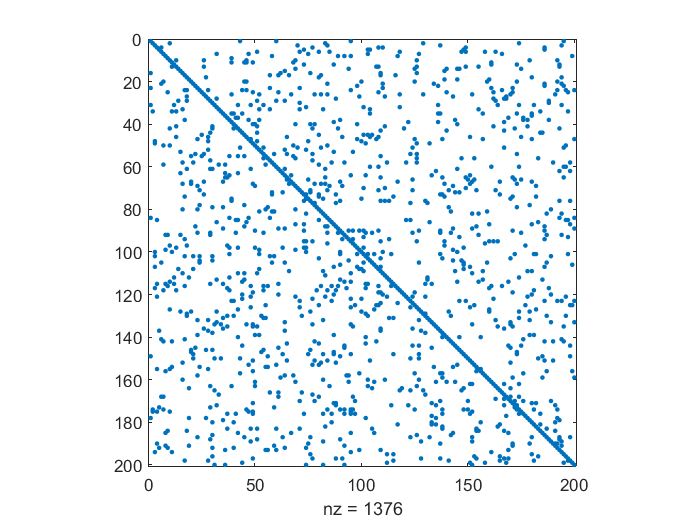

ans = struct with fields:
          cond: 9.779263070235286
     erroreRel: 8.881784197001244e-16
    residuoRel: 2.758248405764645e-16
         niter: 131


% La matrice A è diagonale in modo che gli autovalori coincidano con 
% gli elementi della diagonale principale
n = 200;
A = sprand(n,n,0.03)+spdiags(4*ones(n,1),0,n,n);
x = ones(n,1);

jacobiAccuracy(A,x,eps,1000)

**Test con matrice tridiagonale**

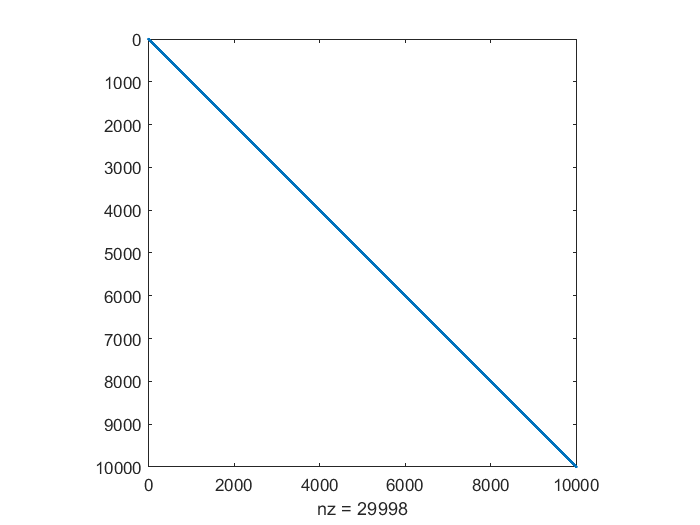

ans = struct with fields:
          cond: 60.999999999999893
     erroreRel: 4.914566982808700e-07
    residuoRel: 4.914569398143151e-07
         niter: 443


n=10000;
A = gallery('tridiag',n,10,31,20);
x=ones(n,1);
% usa eps di default e tol di default 
jacobiAccuracy(A,x)

**Test con matrice A tale che **$\;\rho \left(B\right)<\;1$

Test con matrice A tale che il raggio spettrale della matrice di iterazione $\mathrm{Bj}=I-A^{-1} D$ sia minore di 1 ( $\;\rho \left(\mathrm{Bj}\right)$ è definito come il massimo autovalore di `Bj` ), Per come è definita `Bj` è sufficiente che la matrice `A,`in questo caso diagonale, abbia raggio spettrale < 1 ( gli autovalori di $A^{-1}$ coincidono con quelli di A ). La proprietà che il raggio spettrale sia una quantità minore di 1 è una condizione sufficiente per avere la convergenza dell'algoritmo di Jacobi.

% La matrice A è diagonale in modo tale che gli autovalori coincidano con 
% gli elementi presenti sulla diagonale principale
n = 100;
A = spdiags(rand(n,1),0,n,n);
x = ones(n,1);
max_autovalore = max(eig(A))

max_autovalore =    0.969564627632329


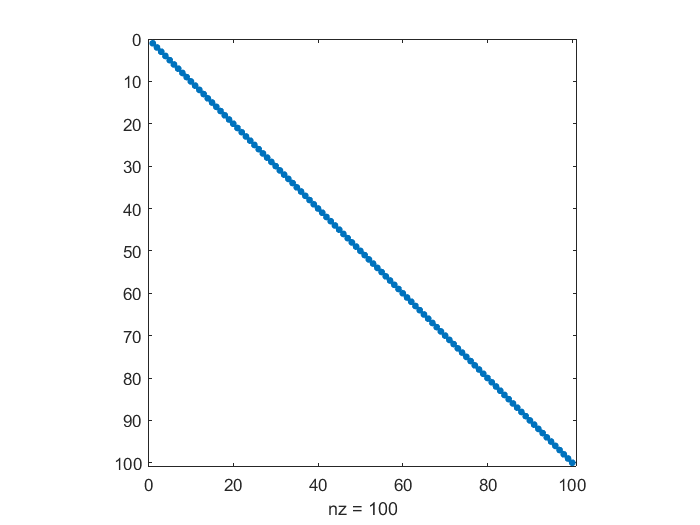

ans = struct with fields:
          cond: 57.215383496869897
     erroreRel: 0
    residuoRel: 0
         niter: 2


jacobiAccuracy(A,x,eps,1000)

**Test con matrice A a diagonale strettamente dominante**

Un ulteriore caso di notevole interesse è quando la matrice  A è a diagonale strettamente dominante, ossia il modulo degli elementi sulla diagonale principale sono più grandi della somma dei moduli degli elementi sulla medesima riga. La condizione di diagonale principale strettamente dominante per `A` implica che il raggio spettrale di `Bj` è una quantità minore di uno ed è quindi una condizione sufficiente per avere la convergenza del metodo di Jacobi

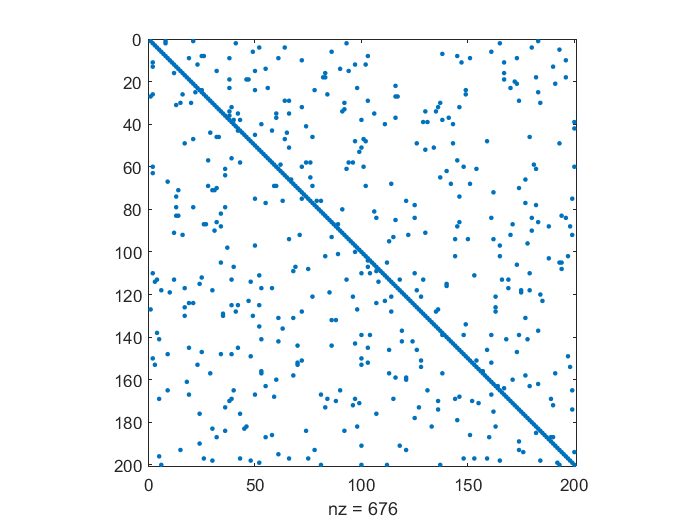

ans = struct with fields:
          cond: 1.519109930809742
     erroreRel: 5.328658736480918e-09
    residuoRel: 4.531351375041027e-09
         niter: 8


n = 200;
% Aggiungiamo a tutti gli elementi sulla diagonale principale la quantità
% 16, in modo tale da verificare la condizione di dominanza
A=sprand(n,n,0.012)+spdiags(16*ones(n,1),0,n,n);
x = ones(n,1);

jacobiAccuracy(A,x)

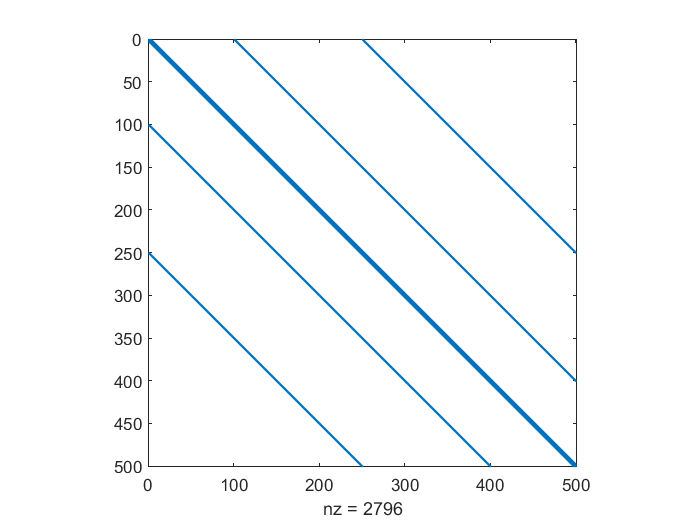

ans = struct with fields:
          cond: 2.498802601781669
     erroreRel: 1.645617582290814e-07
    residuoRel: 1.522812210833093e-07
         niter: 15


n = 500;
onesCol = ones(n,1);
columns = [-onesCol,-2*onesCol, onesCol, 15*onesCol, -onesCol, 2*onesCol,2*onesCol];
d = [-n/2,-n/5, -2, 0, 2, n/5,n/2];
A = spdiags(columns,d,n,n);
x = ones(n,1);

jacobiAccuracy(A,x)

**Test con matrice A tridiagonale con diagonale dominante (dalla gallery)**

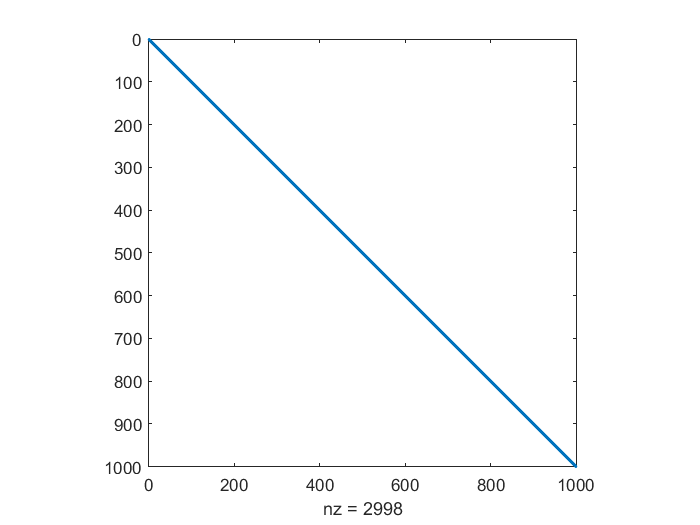

ans = struct with fields:
          cond: 60.999999999999886
     erroreRel: 4.843127632797637e-05
    residuoRel: 4.843362203003932e-05
         niter: 303


n = 1000;
A = gallery('tridiag',1000,10,31,20);
x = ones(n,1);

%eps impostato dall'utente
jacobiAccuracy(A,x,1e-4,2000)

**Test con matrice A di Poisson**

Nel caso in cui la matrice A sia una matrice di Poisson di dimensioni notevoli,anche se l'indice di condizionamento è elevato, si ottiene una soluzione accettabile dal punto di vista dell'errore relativo, ma il numero di iterazioni necessarie all'algoritmo per ottenere la soluzione è elevato, ciò si ripercuote sul tempo necessario per ottenere la soluzione.

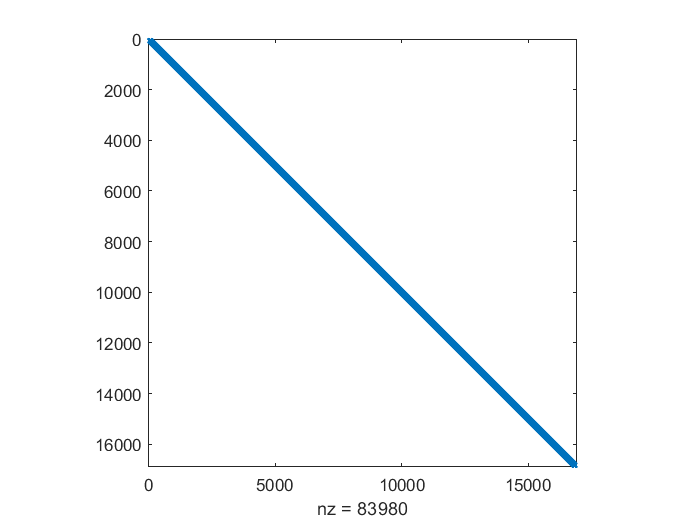

ans = struct with fields:
          cond: 1.011272844784519e+04
     erroreRel: 0.091361436628743
    residuoRel: 5.253694376478046e-05
         niter: 10000


n = 130;
A = gallery('poisson',n);
x = ones(n^2,1);

% L'algoritmo non riesce a converge utilizzando il numero di MAXITER di
% default

b=A*x;
jacobiAccuracy(A,x,1e-7,10000)

ans = struct with fields:
          cond: 1.011272844784519e+04
     erroreRel: 3.476221275706391e-04
    residuoRel: 1.999142105746365e-07
         niter: 29373


n = 130;
A = gallery('poisson',n);
x = ones(n^2,1);

% L'algoritmo non riesce a converge utilizzando il numero di MAXITER di
% default

b=A*x;
jacobiAccuracy(A,x,1e-7,30000)

**Nota**: il numero di cifre significative corrette nella soluzione è 4, a fronte delle 7 richieste tramite il parametro TOL. Ciò è dovuto al condizionamento della matrice dei coefficienti.

# Test di robustezza

Per la progettazione dei casi di test è stato utilizzato il metodo di Category-partition testing [1], ampiamente diffuso nell'ambito dell'Ingegneria del Software per il testing funzionale. In particolare, le categorie sono state scelte in base ai parametri (di ingresso ) modificabili dall'utente e in base agli elementi della matrice `A `che potrebbero violare le condizioni di funzionamento della funzione. I valori sono stati scelti in base alle condizioni di errore/warning in modo tale da verificare che in caso di errori in input i warning e gli errori vengono correttamente scatenati .

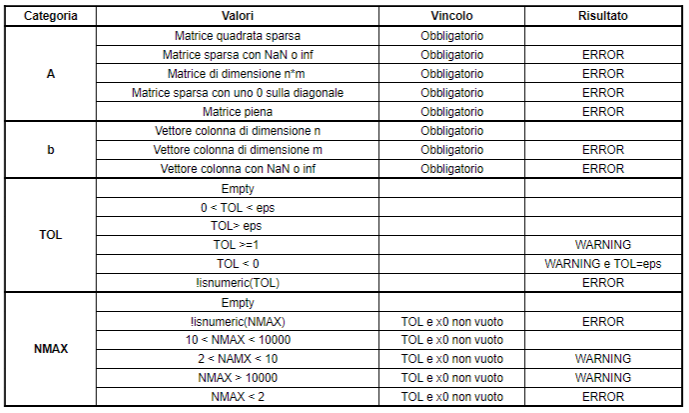

Per l'implementazione dei casi di test è stato utilizzato il framework di MatLab per il testing di unità [2]*; *questa scelta ha permesso di automatizzare completamente l'esecuzione dei test: infatti, è possibile lanciare la simulazione con l'istruzione:

results = runtests('testSuite.m')

Running testSuite
.........
Done testSuite
__________



results =   1×9 TestResult array with properties:

    Name
    Passed
    Failed
    Incomplete
    Duration
    Details

Totals:
   9 Passed, 0 Failed, 0 Incomplete.
   1.1547 seconds testing time.


Il sistema esegue in automatico i test, riportando in `results `un sommario di quanti hanno avuto successo e dettagliando gli errori in quelli che eventualmente sono falliti.

**Nota:** Per semplicità non sono stati implementati i test relativi a dati di input che contenessero valori invalidi `NaN/Inf`.

Di seguito viene descritta l'implementazione di alcuni casi di test a titolo esemplificativo.

## Caso di test 2

- A               : **zero sulla diagonale**

- b               : **valido**

- TOL          : **indifferente**

- MAXITER : **indifferente**

function testFunctionCase2(testCase)

    A = sprand(15,15,0.1);
    A(1,1) = 0;
    x= ones(15,1);
    b = A*x;
    
    testCase.verifyError(@()jacobi(A,b),'jacobi:AZeroOnDiag')
end

L'algoritmo non verrà eseguito perchè la matrice `A `presenta uno zero sulla diagonale principale. Tale condizione viola le ipotesi di funzionamento dell'algoritmo, quindi si impedisce l'esecuzione dell'algoritmo e viene mostrato un messaggio di errore.

## Caso di test 4                                                                                                                         

La configurazione dei parametri è:

- A               : **valido**

- b               : **valido**

- TOL          : **TOL > 1**

- MAXITER : **indifferente**

function testFunctionCase4(testCase)

    A = sprand(10,10,0.1) + speye(10,10);
    x= ones(10,1);
    b = A*x;
    TOL = 10;
    testCase.verifyWarning(@()jacobi(A,b,TOL),'jacobi:TOLtooHigh')
    
end


Viene calcolata la soluzione, ma viene mostrato un warning perchè il valore di `TOL` è troppo grande e quindi la soluzione sarà poco accurata.

## Caso di Test 7

- A               : **valido**

- b               : **non valido**

- TOL          : **indifferente**

- MAXITER : **indifferente**

function testFunctionCase7(testCase)
    
    A = sprand(10,10,0.1) + speye(10,10) ;
    b = rand(10);
    
    testCase.verifyError(@()jacobi(A,b),'jacobi:ColInvalidDimension')
end

Essendo `b` una matrice e non un vettore colonna, la funzione non verrà eseguita e verrà mostrato un messaggio di errore.

# Nota underflow

Inoltre è interessante notare come l'algoritmo implementeato si comporti nel caso in cui viene forzato il verificarsi di una condizione di ***underflow*** nel sistema. In particolare, tale condizione si verifica nel calcolo del prodotto tra `TOL` e `x`, infatti poichè `x` è calcolato mediate passi successivi e `TOL` è un valore piccolo, può verificarsi la condizione di ***underflow*** , cioè il prodotto `TOL*x` viene sostituito da 0. Se ciò accede l'algoritmo non convergerebbe mai. La funzione implementata è robusto rispetto al verificarsi di quest'errore in quanto è stato implementato un controllo sul prodotto, che nel caso si verifichi la condizione di ***underflow*** sostituisce `TOL*x` con `realmin`.

function TOLX = checkUnderflowTOLX(TOL,x)
    TOLX = TOL*norm(x,inf);
    if TOLX < realmin
        TOLX = realmin;
    end
end

## Riferimenti

[1] *Robert D. Cameron, 2013, *[http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html](http://www.cs.sfu.ca/~cameron/Teaching/473/category-partition.html)

[2] Matlab Documentation, [https://it.mathworks.com/help/matlab/function-based-unit-tests.html](https://it.mathworks.com/help/matlab/function-based-unit-tests.html)

## Autore

Gabriele Previtera